# E4 bis

Labelling

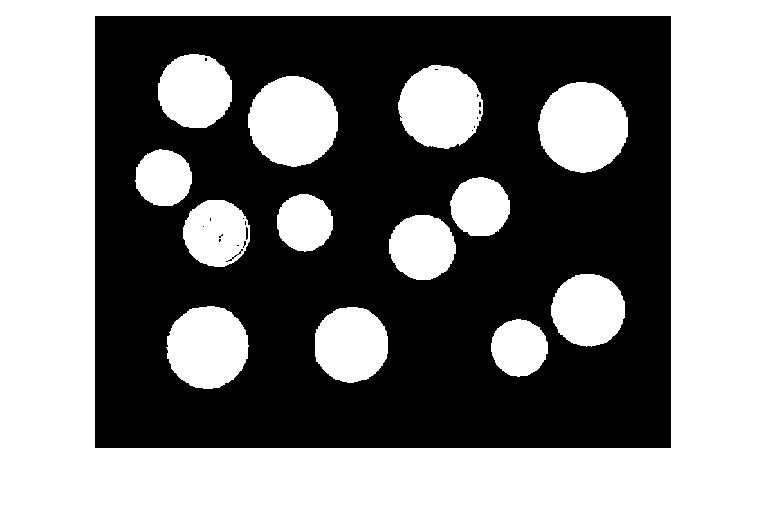

I = imread('money.tif');
BW = I > 100;
imshow(BW);

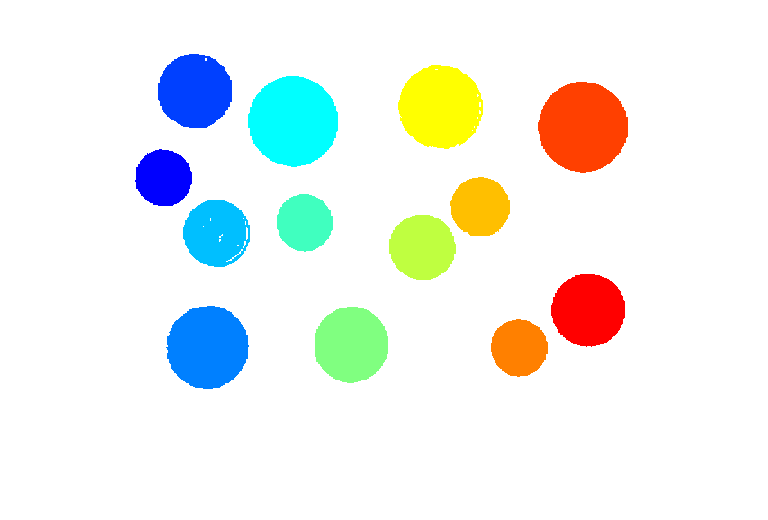

L = bwlabel(BW);
RGB = label2rgb(L);
imshow(RGB);

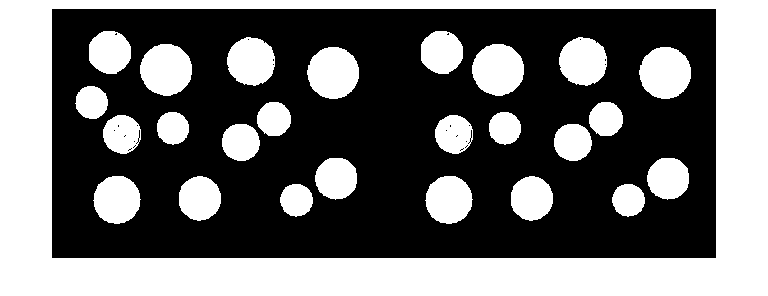

% eliminem la primera moneda
C = bwconncomp(BW);
CBW = BW;
CBW(C.PixelIdxList{1}) = 0;
montage({BW,CBW})

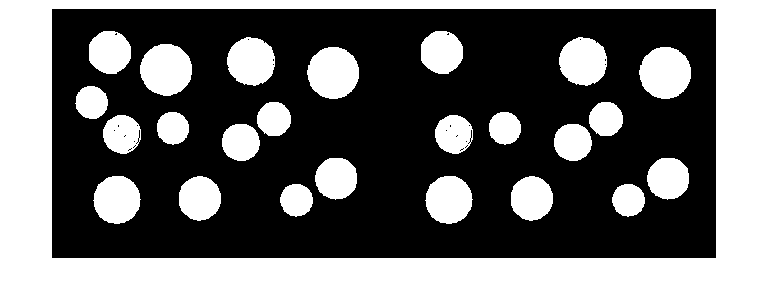

% eliminem la moneda amb més àrea = més píxels
npixels = cellfun(@numel, C.PixelIdxList);
[valormaxim, posicio] = max(npixels);
CBW(C.PixelIdxList{posicio}) = 0;
montage({BW,CBW})

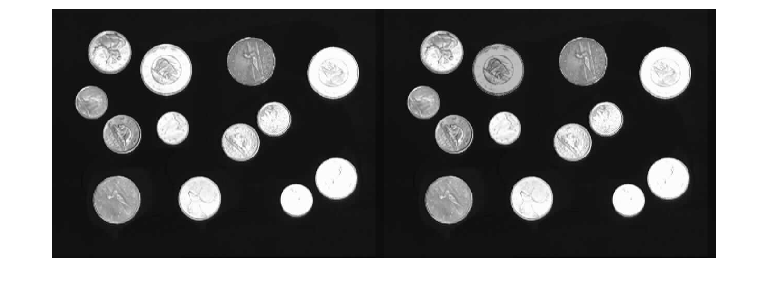

I = imread('money.tif');
% efectes visuals
IC = I;
% enfosquir la moneda més gran
IC(C.PixelIdxList{posicio}) = I(C.PixelIdxList{posicio}) - 64;
montage({I, IC})

Binaritzat segona part

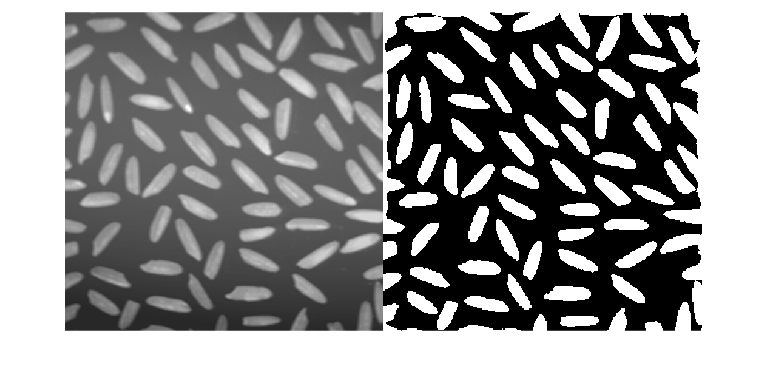

I = imread('arros.tif');
window = [30 30];
M = colfilt(I, window, 'sliding', @mean); 
k = 16;
BW = I > M + k;
%fosc BW = I < M - k;
montage({I,BW});

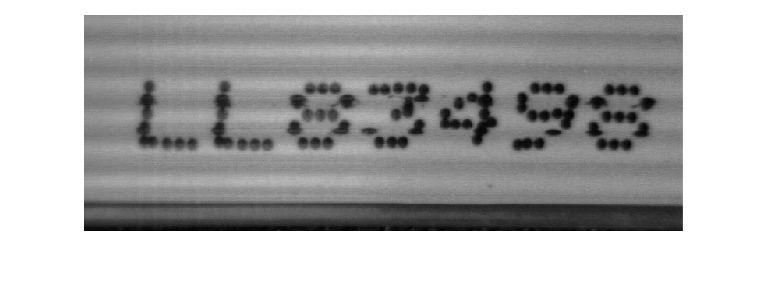

I = imread('FlatCable1.tif');
imshow(I)

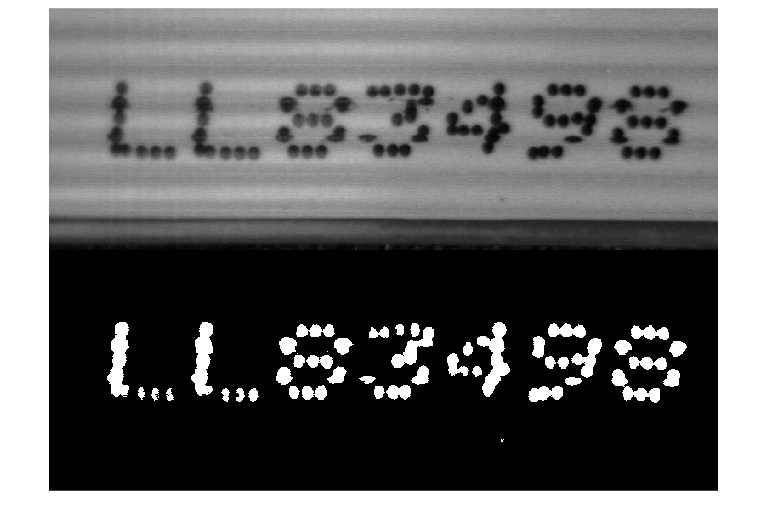

%t = graythresh(I);
%BW = I > 256*t;
window = [1 100];
M = colfilt(I, window, 'sliding', @mean); 
k = 25;
BW = I < M - k;
montage({I,BW})

Exercici

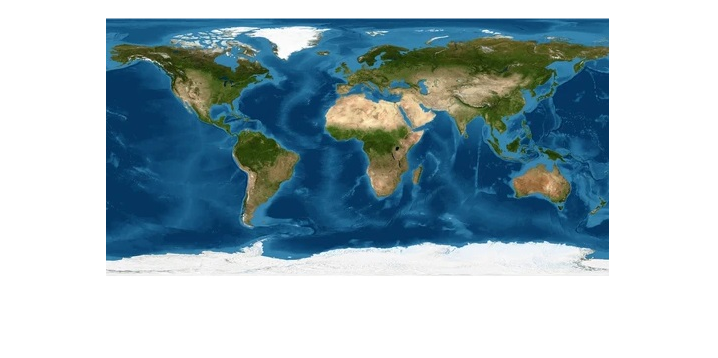

I = imread('mon1.jpg');
imshow(I)

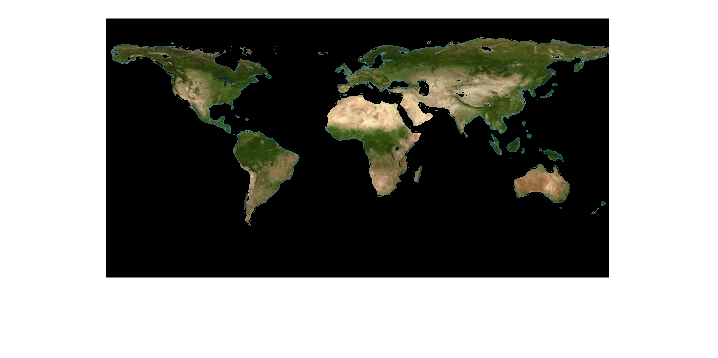

I_hsv = rgb2hsv(I);
h = I_hsv(:,:,1); 
s = I_hsv(:,:,2);
blues = uint8(h < 0.5);
white = uint8(s > 0.2);
R = I(:,:,1);
I = I .* blues .* white;
imshow(I);